srcDir = "..\srcImages\";

barbara = readraw(srcDir + "barbara.raw");

    "→Retrieving Image "    "..\srcImages\barbara.raw"    " ..."



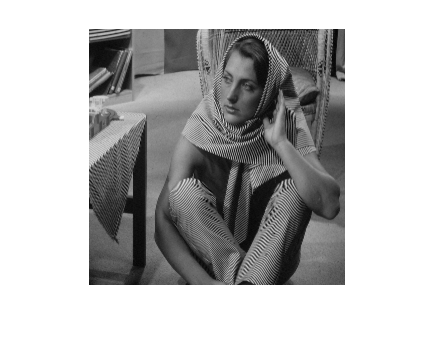

imshow(barbara);

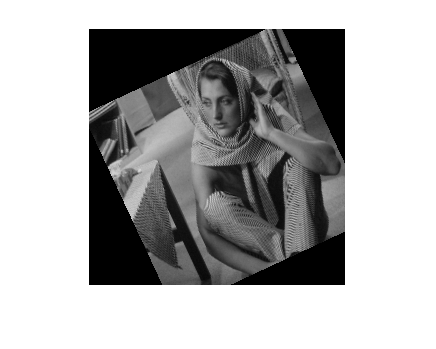


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 5);
imshow(affectedBarbara);

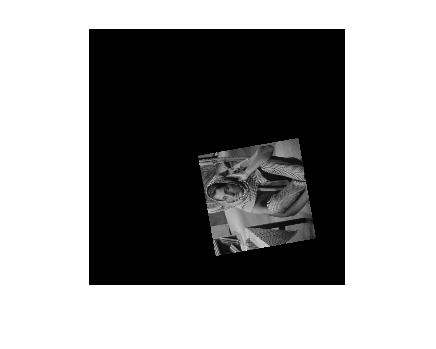


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 20);
imshow(affectedBarbara);

baboon = readraw(srcDir + "baboon.raw");

    "→Retrieving Image "    "..\srcImages\baboon.raw"    " ..."



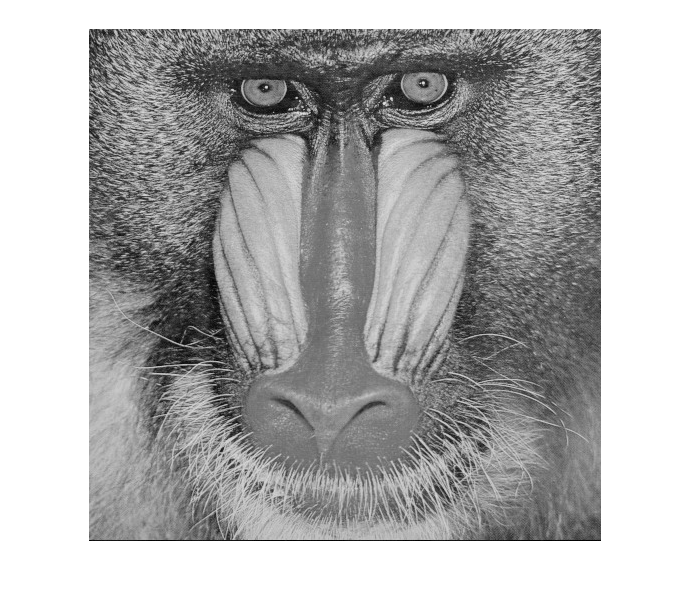

imshow(baboon);

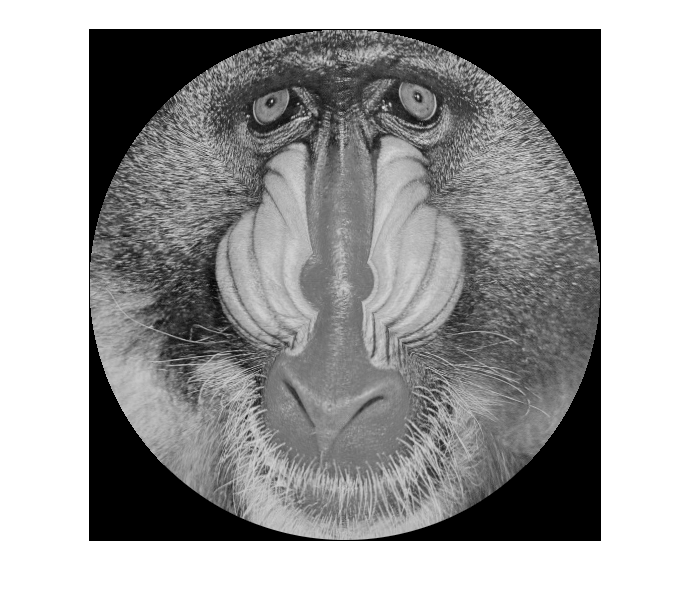


diskBaboon = toDisk(baboon);
imshow(diskBaboon);

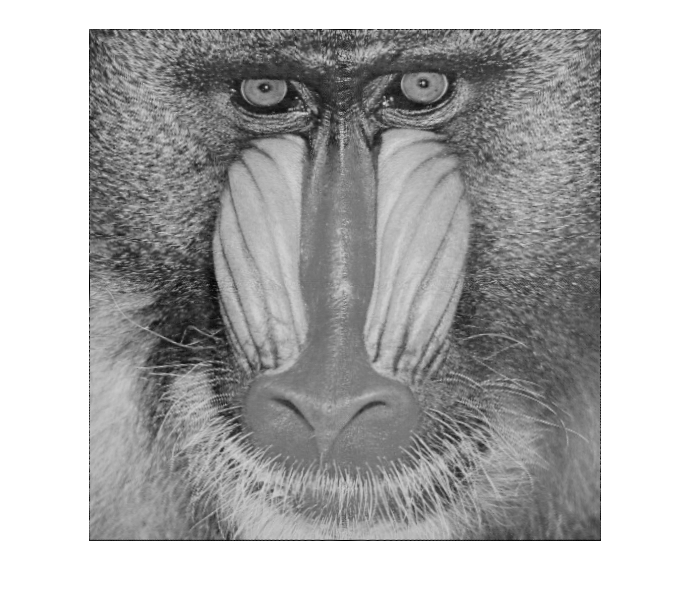


resquaredBaboon = fromDisk(diskBaboon);
imshow(resquaredBaboon);


%diskBaboon = warp(barbara, inverseDisk(128.5));
%imshow(diskBaboon);

%resquaredBaboon = fromDisk(baboon);
%imshow(resquaredBaboon);
%imshow(toDisk(resquaredBaboon));

txClasses = zeros(64, 64, 15);
for i = 1:15
    txClasses(:, :, i) = readraw(srcDir + "sample" + string(i) + ".raw");
end

    "→Retrieving Image "    "..\srcImages\sample1.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample2.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample3.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample4.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample5.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample6.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample7.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample8.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample9.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample10.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample11.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample12.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample13.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample14.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample15.raw"    " ..."




classes = classifyLawsSmallTextures(txClasses, 5);

mosaic1 = readraw(srcDir + "comb1.raw");
imshow(mosaic1);
clustered = clusterTextures(mosaic1, [0, 63, 127, 191, 255]);
imshow(clustered);
segmented = segmentClusters(clustered, [0, 63, 127, 191, 255]);
imshow(segmented);

mosaic2 = readraw(srcDir + "comb2.raw");
imshow(mosaic2);
clustered = clusterTextures(mosaic2, [0, 85, 170, 255]);
imshow(clustered);
segmented = segmentClusters(clustered, [0, 85, 170, 255]);
imshow(segmented);

colors = [0, 85, 170, 255];
connectedParts = connectedComponents(segmented2);
frequencyList = frequencies(connectedParts);
keptComponents = largestComponents(segmented2, connectedParts, [0, 85, 170, 255], frequencyList);
segmented = mergeComponents(connectedParts, frequencyList, keptComponents);
[rows, cols] = size(connectedParts);
for row = 1:rows
    for col = 1:cols
        for i = 1:4
            if segmented(row, col) == keptComponents(i)
                segmented(row, col) = colors(i);
            end
        end
    end
end
imshow(uint8(segmented));

training = toGrayScale(readraw_color(srcDir + "training.raw"));

    "→Retrieving Image "    "..\srcImages\training.raw"    " ..."



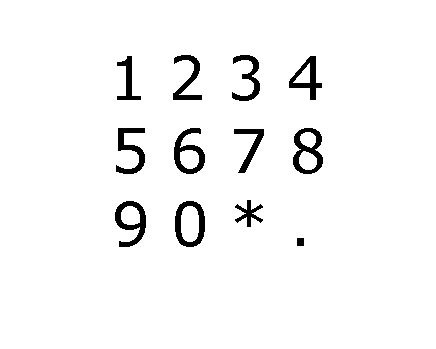

%chars = zeros(85, 64, 12);
%for row = 1:3
%    for col = 1:4
%        startRow = (85 * (row - 1) + 1);
%        startCol = (64 * (col - 1) + 1);
%        chars(:, :, (row - 1) * 4 + col) = training(startRow:(startRow+84), startCol:(startCol+63));
%    end
%end

%for i = 1:12
%    figure;
%    imshow(chars(:, :, i));
%end
imshow(training);


test = connectedComponents(training);
characters = blackConnectedComponents(training);
hullBounds = convexHullsFor(training);

   210

   209

     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0   350   350   350   350   350   350
     0     0     0     0     0   350   350   350   350   350   350
     0     0     0     0     0   350   350   350   350   350   350
     0     0     0     0     0   350   350   350   350   350   350
     0     0     0     0     0   350   350   350   350   350   350
     0     0     0     0     0   350   350   350   350   350   350



    27    71    85   113



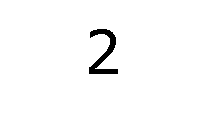

    27    72   144   171



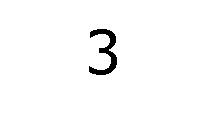

    28    71    29    52



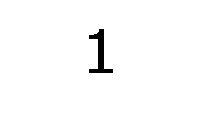

    28    71   201   233



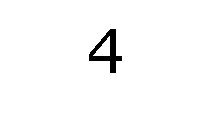

   100   145    28    56



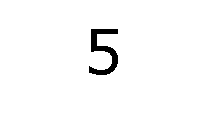

   100   145    86   116



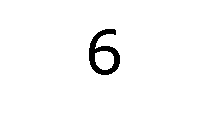

   100   145   205   234



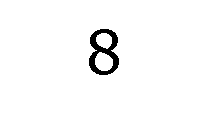

   101   144   146   175



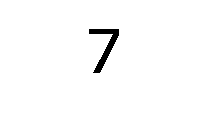

   172   198   147   174



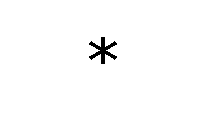

   173   218    27    57



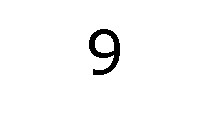

   173   218    87   116



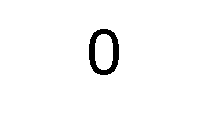

   210   217   209   215



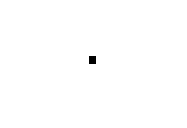

[hulls, ~] = size(hullBounds);
for i = 1:hulls
    figure;
    disp(hullBounds(i, :));
    imshow(binaryImgForBounds(training, hullBounds(i, :)));
end